# 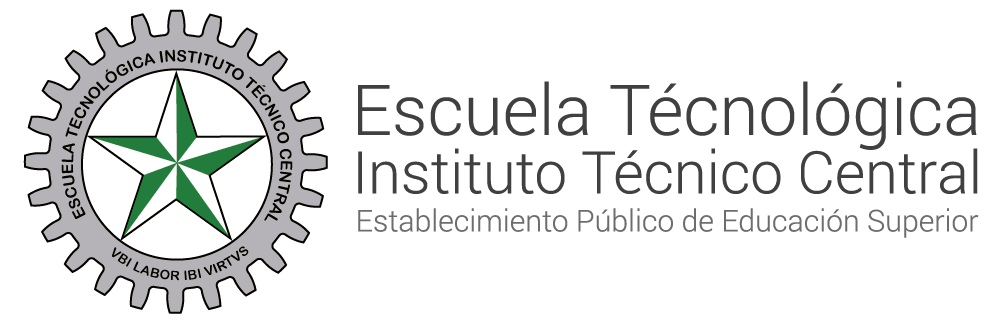

**SISTEMAS DE CONTROL II  **

# **Solución ecuaciones en diferencias**

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c

#### Coautores: **Henry Daniel Mora lozano, Miguel Johany Guayara Gutierrez**

## ¿Que son las ecuaciones en diferencias?

Las ecuaciones en diferencias son herramientas matemáticas que describen cómo una cantidad cambia en pasos discretos, como días, meses o años. Relacionan el valor actual de una variable con sus valores anteriores o posteriores, y son útiles para modelar sistemas que evolucionan en intervalos de tiempo fijos, como el crecimiento de poblaciones, el interés compuesto o la propagación de rumores. En MATLAB, estas ecuaciones se pueden resolver de manera iterativa o mediante fórmulas generales, lo que las hace ideales para simulaciones y análisis numéricos.

Ecuacion en Diferencias de

y[k+2]+3y[k+1]+20y[k]=0 

con condiciones iniciales y(0)=0 ,y(1) =1

utilizamos la definicion de la traformada z de adelanto para la primera funcion ( y[k+2] )


$$\mathcal{L}\left\lbrack y\left(k+n\right)T\right\rbrack =Z^n \left\lbrack y\left(z\right)-\sum_{k=0}^{\infty } y\left(\textrm{kt}\right)z^{-k} \right\rbrack$$


aplicamos trasformada z  para y[k+2]


$$z\left\lbrack y\left(k+2\right)\right\rbrack =z^2 \left\lbrack y\left(z\right)-\left(y\left(0\right)+y\left(1\right)\right)z^{-1} \right\rbrack$$


operamos la funcion, distribuimos $z^2$ para todos los terminos


$$z^2 y\left(z\right)-z^2 y\left(0\right)-z^2 y\left(1\right)z^{-1}$$
 

operamos restando los exponentes 

 
$$z^2 y\left(z\right)-z^2 y\left(0\right)-z^1 y\left(1\right)$$
 

operamos y obtenemos la trasformada de la funcion y[k+2]


$$z^2 y\left(z\right)-z$$


operamos la segunda funcion 3y[k+1]

aplicamos trasformada z


$$z\left\lbrack 3y\left(k+1\right)\right\rbrack =z\left\lbrack y\left(z\right)-y\left(0\right)\right\rbrack$$


operamos la funcion y obtenemos 


$$3z\left\lbrack y\left(k+1\right)\right\rbrack =3z\;y\left(z\right)-3z\;y\left(0\right)\;$$


operamos restando los exponentes 


$$3z\;y\left(z\right)-3z\;y\left(0\right)$$


operamos y obtenemos la trasformada de la funcion 3y[k+1]


$$3z\;y\left(z\right)$$


operamos la tercer funcion 20y[k]

aplicamos trasformada z 


$$z\left\lbrack 20y\left\lbrack k\right\rbrack \right\rbrack =20z\left\lbrack y\left(k\right)\right\rbrack$$


operamos y obtenemos la trasformada de la funcion 20y[k]


$$20y\left(z\right)$$


despues de obtener la trasformada de cada funcion realizamos la sumatoria de la funcion inicial pero en el dominio de Z


$$z^2 y\left(z\right)-z+3\textrm{zy}\left(z\right)+20y\left(z\right)=0$$


operamos para que quede en terminos de y(z), despejamos y obtenemos la transformada z con respecto a la variable de salida


$$\left(y\left(z\right)\right)\left(z^2 +3z+20\right)-z=0$$



$$y\left(z\right)=\frac{z}{z^2 +3z+20}$$


**Paso 3 ( Realizar la expansion en fracciones parciales de la transformada z)**

syms z
numerator = [1 0];
denominator = [1 3 20];
ts=1;
Y_z = tf(numerator,denominator,ts)


Y_z =
 
        z
  --------------
  z^2 + 3 z + 20
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


Ahora procedemos a utilizar la función "residue" con el objetivo de obtener la descomposición en fracciones parciales de la función de transferencia:

[r,p,k] = residue(numerator,denominator)

r =    0.5000 + 0.1780i
   0.5000 - 0.1780i


p =   -1.5000 + 4.2131i
  -1.5000 - 4.2131i



k =

     []



La documentación de matlab nos dice que la fracción parcial se puede reescribir de la siguiente manera:

H_z = (r(1) / (1 - p(1) * z^(-1)) + (r(2) / (1 - p(2) * z^(-1))));

#### Paso 4 (Realizar la transformada inversa de z)

disp(H_z);

$$-\frac{-\frac{1}{2}+\frac{3\,\sqrt{71}\,\mathrm{i}}{142}}{\frac{\frac{3}{2}+\frac{\sqrt{71}\,\mathrm{i}}{2}}{z}+1}-\frac{\frac{1}{2}+\frac{3\,\sqrt{71}\,\mathrm{i}}{142}}{\frac{-\frac{3}{2}+\frac{\sqrt{71}\,\mathrm{i}}{2}}{z}-1}$$

syms k;
simplify(iztrans(H_z ,z,k))

$$ans = -\frac{3\,\sqrt{71}\,{\left(-\frac{3}{2}-\frac{\sqrt{71}\,\mathrm{i}}{2}\right)}^{k}\,\mathrm{i}}{142}+\frac{3\,\sqrt{71}\,{\left(-\frac{3}{2}+\frac{\sqrt{71}\,\mathrm{i}}{2}\right)}^{k}\,\mathrm{i}}{142}+\frac{{\left(-\frac{3}{2}-\frac{\sqrt{71}\,\mathrm{i}}{2}\right)}^{k}}{2}+\frac{{\left(-\frac{3}{2}+\frac{\sqrt{71}\,\mathrm{i}}{2}\right)}^{k}}{2}$$